addpath('Classes')
addpath('Simulink Models')

sympref('FloatingPoint',true);

# Linear Moving Setpoint Controller With Error Polynomial Setting

EXPLANATION HERE

## Augment the System With the Integral of x

An augmented state vector is used in the absolute states. An additional term, the integral of postion, is used so that there is an analagous element to the integral term in the error state vector utilized later:


$$\tilde{x}_{1a} = [
 \int_0^t \!x\, \mathrm{d}t~x ~\dot{x} ~\beta~\dot{\beta}]^T


$$


$A_{1a}$ is the $A_1$ matrix modified to contain the dynamics of the $\int_{0}^{t}xdt~$term. This term's dynamics are simply that its derivative is the $x$ position of the ball. 

A1a = [[0 1 0 0 0];[zeros(4,1),A1]] %Augmented A1 Matrix

$$A1a = \left[\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0\\ 0 & -5.2170 & 0 & 4.0111 & 0\\ 0 & 0 & 0 & 0 & 1\\ 0 & 112.8871 & 0 & 64.8295 & 0 \end{array}\right]$$

$B_{1a}$ is the direct influence of the actuation torque on the system. Since position is not an immediate function of this signal, the augmented matrix recieves another zero element. 

B1a = [0;B1]

$$B1a = \left[\begin{array}{c} 0\\ 0\\ -17.7268\\ 0\\ 383.5785 \end{array}\right]$$


stateVec1a = [ix, x, x_dot, beta, beta_dot].'

$$stateVec1a = \left[\begin{array}{c} \mathrm{ix}\\ x\\ \dot{x}\\ \beta \\ \dot{\beta } \end{array}\right]$$

stateVec1a_dot = [x, x_dot, x_ddot, beta_dot, beta_ddot].'

$$stateVec1a\_dot = \left[\begin{array}{c} x\\ \dot{x}\\ \ddot{x}\\ \dot{\beta }\\ \ddot{\beta } \end{array}\right]$$


EOMS1a_aug = stateVec1a_dot == A1a*stateVec1a + B1a*T_beta

$$EOMS1a\_aug = \left[\begin{array}{c} x=x\\ \dot{x}=\dot{x}\\ \ddot{x}=-5.2170\,x+4.0111\,\beta -17.7268\,T_{\beta }\\ \dot{\beta }=\dot{\beta }\\ \ddot{\beta }=112.8871\,x+64.8295\,\beta +383.5785\,T_{\beta } \end{array}\right]$$

## Define Variables/Matrices Associated With Error Dynamics

A1e = [0 1 0;0 0 1; 0 0 0];
B1e = [0;0;1];
syms a b c

## Derive the Associated Feedback Law

First, define a characteristic polynomial in error dynamics. Utilize a pole placement approch to parameterize its behavior. 

char_poly_ex_eqn = e_x_ddot + a*e_x_dot + b*e_x + c*e_ix == 0

$$char\_poly\_ex\_eqn = a\,e_{\dot{x}}+b\,e_{x}+c\,e_{\mathrm{ix}}+e_{\ddot{x}}=0$$

Substitute the error states for absolute states and setpoint states. 

char_poly_ex_eqn = subs(char_poly_ex_eqn, [e_x_ddot e_x_dot e_x e_ix], [x_ddot_s - x_ddot, x_dot_s - x_dot , x_s - x, ix_s - ix])

$$char\_poly\_ex\_eqn = {\ddot{x}}_{s}-\ddot{x}-c\,\left(\mathrm{ix}-{\mathrm{ix}}_{s}\right)-a\,\left(\dot{x}-{\dot{x}}_{s}\right)-b\,\left(x-x_{s}\right)=0$$

Substitute in the equation for $\ddot{x}$ from the augmented dynamics - brings in the system's physics. 

char_poly_ex_eqn = subs(char_poly_ex_eqn, x_ddot, rhs(EOMS1a_aug(3))) %Replace x_ddot with its dynamic equation

$$char\_poly\_ex\_eqn = 17.7268\,T_{\beta }-4.0111\,\beta +5.2170\,x+{\ddot{x}}_{s}-c\,\left(\mathrm{ix}-{\mathrm{ix}}_{s}\right)-a\,\left(\dot{x}-{\dot{x}}_{s}\right)-b\,\left(x-x_{s}\right)=0$$

The feedback law is the torque $T_\beta$ required to produce the error dynamics specified. 

FB_Law_T_beta = isolate(char_poly_ex_eqn, T_beta)

$$FB\_Law\_T\_beta = T_{\beta }=0.2263\,\beta -0.2943\,x-0.0564\,{\ddot{x}}_{s}+0.0564\,c\,\left(\mathrm{ix}-{\mathrm{ix}}_{s}\right)+0.0564\,a\,\left(\dot{x}-{\dot{x}}_{s}\right)+0.0564\,b\,\left(x-x_{s}\right)$$

Formulate the feedback law as a matrix equation (for Simulink purposes)

M1 = equationsToMatrix(rhs(FB_Law_T_beta), stateVec1a)

$$M1 = \left[\begin{array}{ccccc} 0.0564\,c & 0.0564\,b-0.2943 & 0.0564\,a & 0.2263 & 0 \end{array}\right]$$

setpointVec1 = [ix_s x_s x_dot_s x_ddot_s].'

$$setpointVec1 = \left[\begin{array}{c} {\mathrm{ix}}_{s}\\ x_{s}\\ {\dot{x}}_{s}\\ {\ddot{x}}_{s} \end{array}\right]$$

M2 = equationsToMatrix(rhs(FB_Law_T_beta), setpointVec1)

$$M2 = \left[\begin{array}{cccc} -0.0564\,c & -0.0564\,b & -0.0564\,a & -0.0564 \end{array}\right]$$

## Determine Whether or not the Feedback Stabilizes the System

EOM1aFB = stateVec1a_dot == expand(A1a*stateVec1a + B1a*rhs(FB_Law_T_beta))

$$EOM1aFB = \left[\begin{array}{c} x=x\\ \dot{x}=\dot{x}\\ \ddot{x}=-b\,x+b\,x_{s}+{\ddot{x}}_{s}-a\,\dot{x}+a\,{\dot{x}}_{s}-c\,\mathrm{ix}+c\,{\mathrm{ix}}_{s}\\ \dot{\beta }=\dot{\beta }\\ \ddot{\beta }=21.6383\,b\,x-21.6383\,b\,x_{s}-21.6383\,{\ddot{x}}_{s}+21.6383\,a\,\dot{x}-21.6383\,a\,{\dot{x}}_{s}+151.6229\,\beta +21.6383\,c\,\mathrm{ix}-21.6383\,c\,{\mathrm{ix}}_{s} \end{array}\right]$$

EOM1aFB_check = stateVec1a_dot == simplify(A1a*stateVec1a + B1a*(M1*stateVec1a + M2*setpointVec1))

$$EOM1aFB\_check = \left[\begin{array}{c} x=x\\ \dot{x}=\dot{x}\\ \ddot{x}=-b\,x+b\,x_{s}+{\ddot{x}}_{s}-a\,\dot{x}+a\,{\dot{x}}_{s}-c\,\mathrm{ix}+c\,{\mathrm{ix}}_{s}\\ \dot{\beta }=\dot{\beta }\\ \ddot{\beta }=21.6383\,b\,x-21.6383\,b\,x_{s}-21.6383\,{\ddot{x}}_{s}+21.6383\,a\,\dot{x}-21.6383\,a\,{\dot{x}}_{s}+151.6229\,\beta +21.6383\,c\,\mathrm{ix}-21.6383\,c\,{\mathrm{ix}}_{s} \end{array}\right]$$

CL_A_mat = equationsToMatrix(rhs(EOM1aFB), stateVec1a)

$$CL\_A\_mat = \left[\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0\\ -c & -b & -a & 0 & 0\\ 0 & 0 & 0 & 0 & 1\\ 21.6383\,c & 21.6383\,b & 21.6383\,a & 151.6229 & 0 \end{array}\right]$$

CL_eigs = simplify(eig(CL_A_mat));

% Interestingly enough, placing the poles of the error dynamics puts the poles ...
% of the closed loop system at those locations and two unchangable pole locations...
% (Likely the beta related poles). It would seem like, without stabilizing negative
% feedback from the beta states, they just are what they are regardless of what x is
% doing? I'm really not sure here
roots_error_poly = poly([-20 -5+2*1i -5-2*1i]);
subs(CL_eigs,[a b c],roots_error_poly(2:4)) 

$$ans = \left[\begin{array}{c} -5.0000-2.0000\,\mathrm{i}\\ -12.3135\\ 12.3135\\ -5.0000+2.0000\,\mathrm{i}\\ -20+7.3468e-40\,\mathrm{i} \end{array}\right]$$

M1 = subs(M1 ,[a b c],roots_error_poly(2:4))

$$M1 = \left[\begin{array}{ccccc} 32.7188 & 12.6240 & 1.6924 & 0.2263 & 0 \end{array}\right]$$

M2 = subs(M2 ,[a b c],roots_error_poly(2:4))

$$M2 = \left[\begin{array}{cccc} -32.7188 & -12.9183 & -1.6924 & -0.0564 \end{array}\right]$$

## Create Data and Functions for Simulation (Moving Setpoint Controller)

A1a_sim = double(A1a);
B1a_sim = double(B1a);
M1_sim = double(M1);
M2_sim = double(M2);
C1_polyset = [1 0 0 0  0; 0 1 0 0 0 ; 0 0 1 0 0];

### Moving Setpoint Parameters

r_sim = 150; % radius of circular trajectory [mm]
omega_sim =  2*pi/4; %angular frequency of circular trajectory 

des_traj_sym(t) = r_sim*sin(omega_sim*t);

### Overlay a fist order response so that the desired trajectory is smoothed out a bit

T = (2*pi/omega_sim)/5; %Time constant of the first order response that smooths out the trajectory
des_traj_sym(t) = (1 - exp(-(t/T)))*des_traj_sym;

### Find Integral and Derivatives of Trajectory

int_des_traj_sym(t) = int(des_traj_sym,t);

int_des_traj_sym(t) = int_des_traj_sym(t) - int_des_traj_sym(0)

$$int\_des\_traj\_sym(t) = 5.8468e+03\,{\mathrm{e}}^{-0.0125\,t}\,\cos\left(0.0157\,t\right)-9.5493e+03\,\cos\left(0.0157\,t\right)+4.6527e+03\,{\mathrm{e}}^{-0.0125\,t}\,\sin\left(0.0157\,t\right)+3.7025e+03$$

des_traj_sym_dot(t) = diff(des_traj_sym(t),t)

$$des\_traj\_sym\_dot(t) = 1.8750\,{\mathrm{e}}^{-0.0125\,t}\,\sin\left(0.0157\,t\right)-2.3562\,\cos\left(0.0157\,t\right)\,\left({\mathrm{e}}^{-0.0125\,t}-1\right)$$

des_traj_sym_ddot(t) = diff(des_traj_sym_dot(t),t)

$$des\_traj\_sym\_ddot(t) = 0.0589\,{\mathrm{e}}^{-0.0125\,t}\,\cos\left(0.0157\,t\right)-0.0234\,{\mathrm{e}}^{-0.0125\,t}\,\sin\left(0.0157\,t\right)+0.0370\,\sin\left(0.0157\,t\right)\,\left({\mathrm{e}}^{-0.0125\,t}-1\right)$$

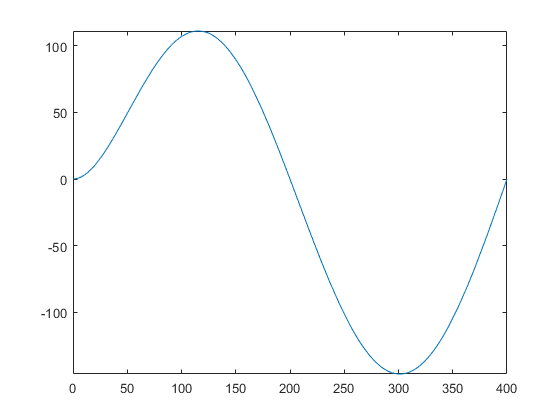

fplot(des_traj_sym) 
xlim([0 2*pi/omega_sim]);

des_traj_handle = matlabFunction([int_des_traj_sym(t);des_traj_sym(t);des_traj_sym_dot(t);des_traj_sym_ddot(t)]);

## Simulate the Controller and Find Out if the Unstable Pole is Actually an Issue

%Specify simulation time
% t_sim = 2*pi/omega_sim;
t_sim = 1;
%Specify initial conditions
x1a_0 = [0 0 0 0 0]; %As if the ball was at rest in the center of the plate - the control objective of any regulator designed for the system

out = sim('Linear_Moving_Setpoint_Poly_Setting');